# SRK方程计算天然气密度和体积

`P、Pc-压力单位，kPa`

`T-温度单位，K；T=t+273.15,t摄氏度，℃`

`R-气体常数，8.3143,kJ/（kmol·K）`

`V-摩尔体积，m3/kmol`

clc;clear;% 清屏，清除所有变量
% CH4 C2H6 C3H8 i-C4H10 n-C4H10 i-C5H12 n-C5H12 C6H14
% C7H16 C8H18 C9H20 C10H22 N2 CO2 H2S H2 H2O He O2
W=inputdlg({'请输入压力，单位kPa','请输入温度，单位℃'},...
    '压力和温度',1,{'101.325','26.85'},'on');
p=str2double(char(W(1)))% 系统压力，kPa

p = 101.3250

T=str2double(char(W(2)))+273.15% 系统温度，K

T = 300

R=8.3143% 气体常数, kJ/（kmol·K）

R = 8.3143

p0=101.325%kPa,一个大气压

p0 = 101.3250

V0=R.*T./p0

V0 = 24.6167

[fid,errmsg]=fopen('SRK.xls','r');
y=xlsread('SRK.xls',3,'A8:S8');%各组分摩尔百分含量
fclose(fid);
load MySRKdatakPa.mat%Pa
%以下为单组分计算。Tc为一个数组，Tr也是一个数组
Tri=T./Tci;
Pri=p./Pci;%%%%%%%%%%%%Pa%%%
mi=(0.480+1.574.*wi-0.176.*wi.^2);
rfai=(1+(1-Tri.^0.5).*mi).^2; 
rfai(16)=(1.096*exp(-0.15114.*Tri(16))).^2;%对于氢
aci=(0.42748.*R.^2.*Tci.^2./Pci);%%%%%%%%%%%%%Pa%%%%%%R^2与Pci不对等%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ai=aci.*rfai;%%%%%%%%%%%%%Pa%%%%%%R^2与Pci不对等%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Ai=0.42748.*rfai.*Pri./Tri.^2;
bi=0.086640.*R.*Tci./Pci;
dai=-mi.*(ai.*aci).^0.5./(T.*Tci).^0.5;%单一组分温度1阶偏导数(本书公式)
%%%%%%%%%%%%%Pa%%%%%%R^2与Pci不对等%%%%%%%%%%%%%%%%%%%%%%%%%%%%
dai2=mi.*aci.*(1+mi)./(2.*T.*(Tci.*T).^0.5);%单一组分温度2阶偏导数(本书公式)
%%%%%%%%%%%%%Pa%%%%%%R^2与Pci不对等%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%以上为数组计算，等同于for循环
TcM=sum(y.*Tci)

TcM = 213.6448

PcM=sum(y.*Pci)%%%%%%%%%%%%%%Pa%%%%%%%%%

PcM = 4.6893e+03

TrM=T./TcM

TrM = 1.4042

PrM=p./PcM

PrM = 0.0216

M=sum(y.*Mwi)

M = 18.8483

b=sum(y.*bi)

b = 0.0327

a=0; TdadT1=0;dadT1=0;dadT3=0;dadT7=0;a_TdadT=0;
FAC2=0;D2aDT20=0;D2aDT23=0;D2aDT25=0;
for i=1:19
   for j=1:19
       a=y(i).*y(j).*(1-Kij(i,j)).*ai(i).^0.5.*ai(j).^0.5+a;
       TdadT1=-y(i).*y(j).*(1-Kij(i,j)).*mi(j).*...
           (ai(i).*aci(j).*Tri(j)).^0.5+TdadT1; %石油及天然气物性预测
       dadT1=-R/2.*(0.42748./T).^0.5.*y(i).*y(j).*(1-Kij(i,j)).*...
           (mi(i).*(ai(j).*Tci(i)./Pci(i)).^0.5+...
           mi(j).*(ai(i).*Tci(j)./Pci(j)).^0.5)+dadT1;%kPa
          %流体热物性学——基本理论与计算=============
       dadT3=-y(i).*y(j).*(1-Kij(i,j)).*mi(j).*(ai(i).*aci(j)....
           /(T.*Tci(j))).^0.5+dadT3;
       %施云海+陈钟秀+胡望明. 化工热力学
       dadT7=0.5.*y(i).*y(j).*(1-Kij(i,j)).*...
           ((ai(j)./ai(i)).^0.5.*dai(i)+...
           (ai(i)./ai(j)).^0.5.*dai(j))+dadT7;
       %Thermodynamic properties involving derivatives Using the Peng-Robinson equation of state.pdf
       %%%%%%%%%%%%%Pa%%%%%%R^2与Pci不对等%%%%%%%%%%%%%%%%%%%%%%%%%%%%
       %%%%以上公式已经检验形式准确==============
       a_TdadT=y(i).*y(j).*(1-Kij(i,j)).*(Ai(i).*Ai(j)).^0.5.*...
           (1+mi(i).*Tri(i).^0.5./2./rfai(i).^0.5+...
              mi(j).*Tri(j).^0.5./2./rfai(j).^0.5)+a_TdadT;%p102*4.3-15
       %Applications of the Soave–Redlich–Kwong Equation of State Using Mathematica
       %MODELING OF MULTICOMPONENT MULTISTAGE SEPARATION PROCESSES
        %%%%以上公式已经检验形式准确==============
        FAC2=y(i).*y(j).*(1-Kij(i,j)).*(ai(i).*ai(j)).^0.5.*...
           (1+mi(i).*Tri(i)^0.5./2./rfai(i).^0.5+...
              mi(j).*Tri(j)^0.5./2./rfai(j).^0.5)+FAC2;%p102，4.3-16
          %%%%%%%%%%%%%Pa%%%%%%R^2与Pci不对等%%%%%%%%%%%%%%%%%%%%%%%%%%%%
       D2aDT20=0.5.*y(i).*y(j).*(1-Kij(i,j)).*...
           (dai(i).*dai(j)./(ai(i).*ai(j))^0.5+...
           dai2(i).*ai(j)^0.5./ai(i)^0.5+...
           dai2(j).*ai(i)^0.5./ai(j)^0.5-...
           0.5*(dai(i)^2.*ai(j)^0.5./ai(i)^1.5+...
                dai(j)^2.*ai(i)^0.5./ai(j)^1.5))+D2aDT20;%原始推导公式未简化4.8-26
            %%%%%%%%%%%%%Pa%%%%%%R^2与Pci不对等%%%%%%%%%%%%%%%%%%%%%%%%%%%%
       D2aDT23=0.5.*y(i).*y(j).*(1-Kij(i,j)).*...
            mi(i).*(aci(i))^0.5./(T.*Tci(i))^0.5.*...
           (mi(j).*aci(j)^0.5./(T.*Tci(j))^0.5+ai(j)^0.5./T)+D2aDT23;%p114简化版4.8-27
       %%%%%%%%%%%%%Pa%%%%%%R^2与Pci不对等%%%%%%%%%%%%%%%%%%%%%%%%%%%%
       D2aDT25=-0.5.*y(i).*y(j).*(1-Kij(i,j)).*...
           mi(j).*aci(j)^0.5./Tci(j)^0.5.*...
           (dai(i)./(T.*ai(i))^0.5-ai(i)^0.5./T^1.5)+D2aDT25;%%p115简化版4.8-28*20、23、25结果一样
       %%%%%%%%%%%%%Pa%%%%%%R^2与Pci不对等%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   end
end
a 

a = 237.2628

dadT1  

dadT1 = -0.5434

D2aDT20

D2aDT20 = 0.0015

%%%%气体状态求解摩尔体积的显式化公式%%%%%%%%%
tic
f5=9*R*T/10/p;
f4=a/f5/(b+f5);
f3=p+R*T/(b-f5)+f4;
f2=f4/(b+f5)-R*T/(b-f5)^2+f4/f5;
f1=f3/f2+f5;
f0=f1*(f1+b);
% V=vpa(f1+f3/f2*(p+a/f0-R*T/(f1-b))/(2*R*T/(f1-b)-2*a/f0-p-R*T/(f5-b)+f4),8)
V=f1+f3/f2*(p+a/f0-R*T/(f1-b))/(2*R*T/(f1-b)-2*a/f0-p-R*T/(f5-b)+f4)

V = 24.5543

%V=vpa(V,8)
toc

历时 0.024512 秒。


%%%%气体状态求解摩尔体积的显式化公式%%%%%%%%%
% %---------以下为牛顿法求解方程的根---液态根Z范围0.04-0.4-------------
% tic
%  x(1)=0.9.*R.*T./p;% 设定初值NG
% % x(1)=0.04*R.*T./p;%m3/kmol;1/420*M;%R.*T./p./420*M;%LNG,mol/m3
% % if TrM<=1
% %    x(1)=1./(0.5.*(3-TrM).*PrM);
% %    x(1)=1/(15-8.*TrM.^0.8-1.5.*TrM.^10+1.5.*(1-1));
% % else
% %     x(1)=1./(PrM.*(0.46-0.04.*(2-2)).*(2-(TrM-1).^0.2));
% % end
% for k=1:100%牛顿法求解
% fx(k)=R.*T./(x(k)-b)-a./(x(k).*(x(k)+b))-p;
% f_diff(k)=a/(x(k).*(b + x(k)).^2)-(R.*T)./(b-x(k)).^2+a./(x(k).^2.*(b + x(k)));
% x(k+1)=vpa(x(k)-fx(k)./f_diff(k),12);
%     if (x(k)>0) && (x(k+1)>0) && (abs((x(k+1)-x(k))./x(k))<=10^(-6))
%         k
%         V=vpa(x(k).*1,8)%capicity in m3/mol--0.402979
%         Ro=vpa(1./V*M,8)%density in kg/m3-----52.6898
%        break;
%     end
% end
% toc
% %---------以下为弦截法求解方程的根---液态根Z范围0.04-0.4-------------
% tic
% % if p>1000 && p<2000
% %     x(1)=0.04.*R.*T./p;
% % elseif p=2000
% %     x(1)=
% % end
% x(1)=0.04.*R.*T./p;% 设定初值LNG
% x(2)=0.2.*R.*T./p;% 设定初值LNG
% for k=2:100%牛顿法求解
% fx(k)=R.*T./(x(k)-b)-a./(x(k).*(x(k)+b))-p;
% x(k+1)=vpa(x(k)-fx(k).*(x(k)-x(k-1))./(fx(k)-fx(k-1)),12)
%     if (x(k)>0) && (x(k+1)>0) && (abs((x(k+1)-x(k))./x(k))<=10^(-6))
%         k
%         V=vpa(x(k).*1,8)%capicity in m3/mol--0.402979
%         Ro=vpa(1./V*M,8)%density in kg/m3-----52.6898
%        break;
%     end
% end
% toc

% %---------以下为MATLAB内置求解器求解方程的根----------------
tic
syms x
eqns= R.*T./(x-b)-a./(x.*(x+b))-p;
V= solve(eqns,x,'Real',1)% 只求实数解

$$V = \frac{51293079882131825692140698836753362914095315}{767635818898064699716140724877696723582976\,{\left(\frac{\sqrt{1019879170878125238372055783955705264814854150235466049027849309394022342315805891346425481232750073527823516074770432}\,\sqrt{29282746425154290320153349669777517763490934574613150413455746698599461263284968582867969418235487242244061030798366375}}{1019879170878125238372055783955705264814854150235466049027849309394022342315805891346425481232750073527823516074770432}+\frac{1401422676616933380495792634778081249775752887183366789384475}{2565623500551158592762067677361533405089948706070327197696}\right)}^{1/3}}+{\left(\frac{\sqrt{1019879170878125238372055783955705264814854150235466049027849309394022342315805891346425481232750073527823516074770432}\,\sqrt{29282746425154290320153349669777517763490934574613150413455746698599461263284968582867969418235487242244061030798366375}}{1019879170878125238372055783955705264814854150235466049027849309394022342315805891346425481232750073527823516074770432}+\frac{1401422676616933380495792634778081249775752887183366789384475}{2565623500551158592762067677361533405089948706070327197696}\right)}^{1/3}+\frac{13712504290226995}{1671120235266048}$$

V= vpa(V,8)% 只求实数解

$$V = 24.554309$$

toc

历时 0.462310 秒。


% %---------以上为MATLAB内置求解器求解方程的根----------------
A=a.*p./(R^2.*T^2)

A = 0.0039

B=b.*p./(R.*T)

B = 0.0013

Z=p.*V./(R.*T)

$$Z = 0.99746434063673560800842066322957$$

 %-------理想气体焓熵比热---------
%%以下为TGNET软件中的公式
% %  IA=xlsread('SRK.xls',3,'A37:S37')';%读取A值
%  IB=xlsread('SRK.xls',3,'A38:S38')';%读取B值
%  IC=xlsread('SRK.xls',3,'A39:S39')';%读取C值
%  ID=xlsread('SRK.xls',3,'A40:S40')';%读取D值
%  IE=xlsread('SRK.xls',3,'A41:S41')';%读取E值
%  IF=xlsread('SRK.xls',3,'A42:S42')';%读取F值
%  IG=xlsread('SRK.xls',3,'A43:S43')';%读取G值
% save('MyCHSdata.mat','IA','IB','IC','ID','IE','IF','IG')
load MyCHSdata.mat
IT=9*T/5;
    H1=sum(y'.*2.326122.*(IA+IB.*IT+IC.*IT^2+ID.*IT^3+IE*IT^4+IF.*IT^5));%比焓 kJ/kg
    Cp1=sum(y'.*4.187020.*(IB+2*IC.*IT+3*ID.*IT^2+4*IE.*IT^3+5*IF.*IT^4));%定压比热  kJ/(kg·K)
    S1=sum(y'.*4.187020.*(IB.*log(IT)+2*IC.*IT+3./2*ID*IT^2+4./3*IE*IT^3+5/4*IF.*IT^4+IG));%比熵 kJ/(kg·K)  
%because the unit of DeltH, DeltS, DeltCv, DeltCp are use kmol,so,the
%following parameters are convert to kmmol
    Cp0= Cp1.*M%kJ/(kmol·K)

Cp0 = 40.6800

    Cv0=Cp0-R%kJ/(kmol`K)%%%%%%%%%%%%

Cv0 = 32.3657

% Cp0*M%kJ/(kmol·K)
% % Cv0=Cp0*M-R/1000%kJ/(kmol`K)%%%%%%%%%%%%R=8.3143kJ/(kmol`K)
%  Cv0=Cp0-R/M/1000%kJ/(kg`K)%%%%%%%%%%%%
H0=H1.*M %kJ/kmol

H0 = 1.0987e+04

S0=S1.*M%kJ/(kmol·K)

S0 = 204.3620

 %%----------%焓-------
% DeltH1=0; DeltH2=0; DeltH3=0;DeltH6=0;DeltH7=0; DeltH8=0; DeltH11=0;
 DeltH1=vpa(R.*T.*(Z-1-1./(b.*R.*T).*(a-TdadT1).*log(1+b./V)),6)%kJ/kmol，与R*K单位一致，石油及天然气物性预测

$$DeltH1 = -22.6159$$

 DeltH2=vpa(R.*T.*(Z-1-1./(b.*R.*T).*(a-T.*dadT1).*log(1+b./V)),6);%流体热物性学——基本理论与计算
 DeltH7=vpa(R.*T.*(Z-1-1./(b.*R.*T).*(a-T.*dadT7).*log(1+b./V)),6);%
 % %Thermodynamic properties involving derivatives Using the Peng-Robinson equation of state.pdf
 DeltH11=vpa(R.*T.*(Z-1-R.*T./(b.*p)*(a_TdadT).*log(1+b./V)),6); %p86*4.3-15
 %MODELING OF MULTICOMPONENT MULTISTAGE SEPARATION PROCESSES
 %Applications of the Soave–Redlich–Kwong Equation of State Using Mathematica
 DeltH8=vpa(R.*T.*(Z-1-1./(b.*R.*T).*(FAC2).*log(1+b./V)),6); %p86*4.3-16
 %MODELING OF MULTICOMPONENT MULTISTAGE SEPARATION PROCESSES
 DeltH3=vpa(R.*T.*(Z-1-1./(b.*R.*T)*(a-T.*dadT3).*log(1+b./V)),6);%施云海+陈钟秀+胡望明. 化工热力学-1569311.0
 % % %以上各式相等
 DeltH30=vpa(R.*T.*(Z-1-A./B.*(1-T.*dadT1./a).*log(1+B./Z)),6);%p85*4.3-10
 DeltH6=vpa(R.*T.*(Z-1-1./(b.*R.*T).*(a-T.*dadT1).*log(1+b./V)),6); %p85*4.3-10
  %%%--------熵--------------
 DeltS1=vpa(R.*(log(p.*(V-b)./R./T)+1./(b.*R.*T).*TdadT1.*log(1+b./V)-log(p./p0)),6)%kJ/(kmol`K) 与R单位一致

$$DeltS1 = -0.0543021$$

 % 石油及天然气物性预测+Calculation-Of-Volumetric-And-Thermodynamic-Properties-For-Pure-Hydrocarbons-And-Their-Mixtures-Using-Cubic-Equations-Of-State.pdf
DeltS3=vpa(R.*(log(1-b./V)+1./(b.*R).*dadT7.*log(1+b./V)+log(p0.*V./R./T)),6);%%天然气管道输送（第二版），负号变正号后结果与其它一致
DeltS4=vpa(R.*(log(1-b./V)+log(V./V0)+1./(b.*R).*dadT1.*log(1+b./V)),6);%童景山. 流体热物性学——基本理论与计算+流体的热物理性质-童景山-北京：中国石化出版社-1996.pdf
%-36336.1以上各式相等
%DeltS2=vpa(R.*(log(p.*V./R./T-b.*p./R./T)-a.*(R.*T.*b).*(mi.*Tr.^0.5./(1+mi.*(1-Tr.^0.5))).*log(1+b./V)),6)%Chemical_Engineering_Computation_with_MATLAB
%DeltS2=vpa(-R.*log(R.*T./p0./V)+R.*log(1-b./V)-1/b.*dadT1.*log(1+b./V),6)%天然气管道输送（第二版）-李长俊-北京：石油工业出版社-2008.9.pdf,混合规则用的童景山的
% 施云海，王艳莉，彭阳峰等+陈钟秀.
% 化工热力学，无混合规则+Chemical_Engineering_Computation_with_MATLAB，无混合规则,修正后和石油及天然气物性预测一致
%%%-----------比热---------------
DeltCv=vpa(T/b*D2aDT20*log(1+b/V),6)%与R单位相同

$$DeltCv = 0.0186562$$

dpdT=R/(V-b)-dadT7/(V*(V+b));
dpdV=a*(2*V+b)/V^2/(V+b)^2-R*T/(V-b)^2;
%dp2dV2=2*R*T/(V-b)^3+2*a/(V^2+2*b*V-b^2)^2-2*a*(2*V+2*b)^2/(V^2+2*b*V-b^2)^3;
DeltCp=vpa(-T*dpdT^2/dpdV+DeltCv-R,6)%与R单位相同

$$DeltCp = 0.12782$$

DeltCp1=vpa(T/b*D2aDT25*log(1+b/V)-R+...
    T*(R/(V-b)-dadT7/V/(V+b))^2/(R*T/(V-b)^2-a*(2*V+b)/V^2/(V+b)^2),6);
%以上两式相等%

H=vpa(H0.*M+DeltH1,6)%kJ/kmol

$$H = 207056.0$$

S=vpa(S0.*M+DeltS1,6)%kJ/(kmol·K)

$$S = 3851.82$$


Cv=(Cv0+DeltCv)%kJ/(kmol·K)%/M--%kJ/(kg`K)

$$Cv = 32.384360448063814419435985444304$$

Cp=(Cp0+DeltCp)%kJ/(kmol·K)%/M--%kJ/(kg`K)

$$Cp = 40.807824131398668499521078012247$$

%%%--------------比热比--------------------------
kCpCv=Cp./Cv

$$kCpCv = 1.260109002209382009875010251113$$

%%%---------kT-----等温压缩性(isothermal compressibility)-------------------------
kT=-1/V./dpdV %kJ/m3

$$kT = 0.0098943164058163228565503038214724$$

%%%-----------ks---绝热压缩性或等熵压缩性(Adiabatic compressibility或isentropic compressibility)-------------------------
ks=-Cv./Cp.*kT%kJ/m3

$$ks = -0.0078519527981058460831781211133145$$

%%%---------β为体积膨胀系数(coefficient of volume expansion)-------------------------
betaV=-1/V.*dpdT./dpdV%1/K

$$betaV = 0.0033636729896883906896597919666033$$

%%%------JT系数----K/kPa-------
UJ=vpa(1/Cp.*(-T*dpdT/dpdV-V),6)%K/kPa

$$UJ = 0.00547667$$

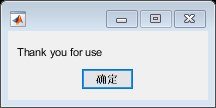

%end
% pause
% h=msgbox('its over','end','warn');
% waitfor(h);
msgbox({'Thank you for use'});